obj =   Image with properties:

           CData: [256×256 double]
    CDataMapping: 'scaled'

  Show all properties


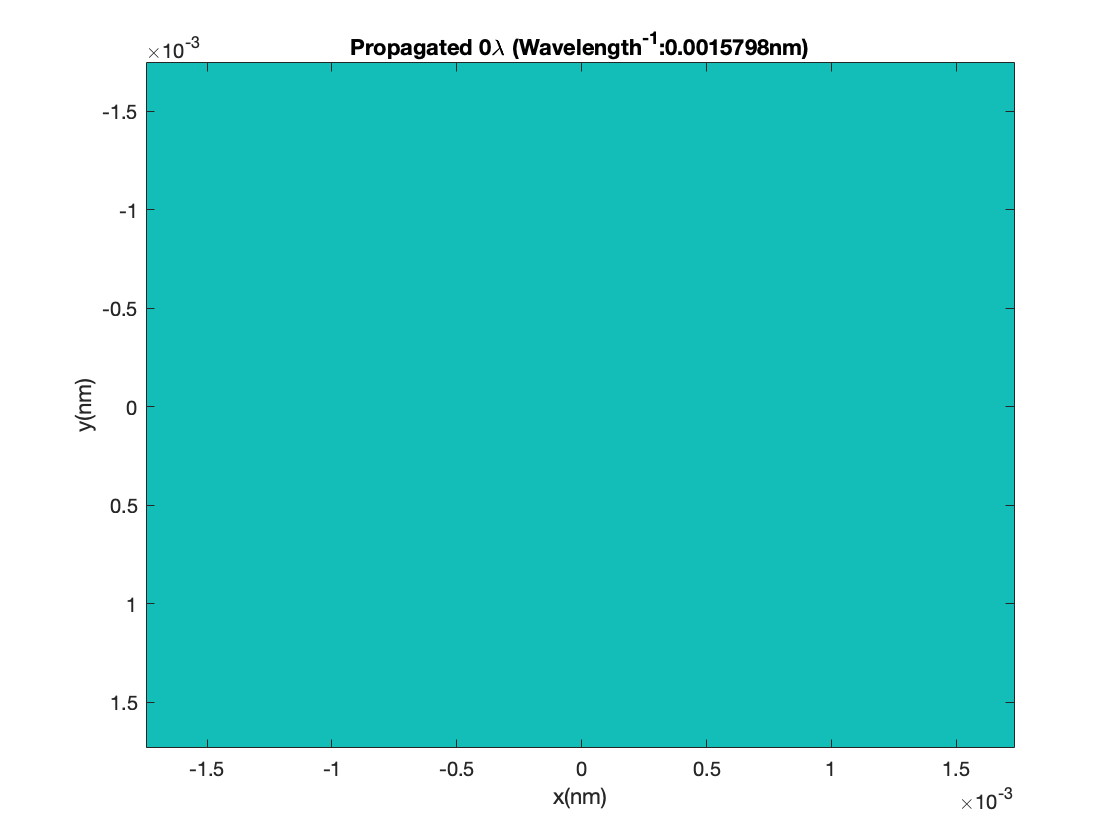

Unrecognized function or variable 'Export_fig'.

N = 257; % sampling points
lambda = 633; % wavelength
k = 2*pi/lambda;
z = (0:0.1:10)*lambda;
z = reshape(repmat(z,256*256,1),256,256,[]);
Endpoint = 1.1/lambda;

x = linspace(-Endpoint,Endpoint,N); % makes sure that the median is 0
x = x(1:end-1); % remove duplicate values
dx = x(2)-x(1);
y = linspace(-Endpoint,Endpoint,N);
y = y(1:end-1);
dy = y(2)-y(1);

[X,Y]=meshgrid(x,y);

Uph = exp(2*pi*1i*sqrt((lambda^-2)-(X.^2+Y.^2)).*z);



for ii = 1:size(z,3)
    obj = imagesc(x,y,real(Uph(:,:,ii)))
    title(['Propagated ' num2str(z(1,1,ii)/lambda) '\lambda (Wavelength^{-1}:' num2str(1/lambda) 'nm)' ])
    xlabel('x(nm)')
    ylabel('y(nm)')
%     exportgraphics(obj, gifFile);
%     print(['HW4_Q1.pdf'],'-dpdf','-bestfit');
%     exportgraphics(gcf,'testAnimated.gif','Append',true);
%     imwrite(A ,,"testAnimation","gif","LoopCount",Inf,"DelayTime",1);
    export_fig(['temp\Q1_' num2str(ii)],'-pdf','-q101')
    
end